# Супер-пупер скрипт для лабок по общесосу

close all
clear variables

prompt = 'Please, enter the number of series of experiment ';
number_of_series = double(string(inputdlg(prompt, 'Number of series')))

number_of_series = 1



MV = cell(number_of_series, 1);
SSQ = cell(number_of_series, 1);
SSQ_delta = cell(number_of_series, 1);

fg = figure;
hold on

for i = 1:number_of_series

## Вводим столбец значений по оси абсцисс

    prompt = {'Please, enter the name of file containig X values ', 'Please, enter the name of file containig Y values '} ;
    filenames = inputdlg(prompt, 'File names', [1 50; 1 50])
    filename(1) = append(string(filenames(1)), '.csv')
    filename(2) = append(string(filenames(2)), '.csv')

## Вводим столбец значений по оси ординат

    x_colomn = importdata(filename(1));
    y_colomn = importdata(filename(2));
    %clc;

## Считаем всё по МНК

    MV(i) = {medium_values(x_colomn, y_colomn)};
    SSQ(i) = {smallest_squares_method(x_colomn, y_colomn, 1)}; % используем свою функцию, потому что потом можно будет прикрутить всё к ней
    SSQ_delta(i) = {smallest_squares_method_delta(cell2mat(MV(i)), cell2mat(SSQ(i)), size(x_colomn, 1))};

## А это тест

%TEST
% x_colomn = (1:10)';
% y_colomn = x_colomn + randn(10,1);

% MV = medium_values(x, y1);
% SSQ = smallest_squares_method(x, y1, 1);
% SSQ_delta = smallest_squares_method_delta(MV, SSQ, size(x, 1));
%END OF TEST

## А это построение графика

надо запилить функцию с вводом параметров построения

%MAKE A FUNCTION
    %fg = figure; points disappearing if this uncommented 
    prompt = {'Please, enter the name of scatter plot color: (default values are recommended)', 'Please, enter the name of scatter type: (default values are recommended)'};
    scatter_info = inputdlg(prompt, 'Scatter info', [1 50; 1 50], {'blue', '.'});
    scatter(x_colomn, y_colomn, 25, string(scatter_info(1)), string(scatter_info(2)))
    
    fitting_data = cell2mat(SSQ(i));
    
    yfit = fitting_data(1)*x_colomn+fitting_data(2);
    
    prompt = {'Please, enter the name of plot color: ', 'Please, enter the line type: (default values are recommended)'};
    plot_info = inputdlg(prompt, 'plot info', [1 50; 1 50], {'blue', '-'});
    plot_parameters = append(string(plot_info(1)), string(plot_info(2)));
    
    prompt = 'Please, enter the width of line: ';
    width_info = str2double(inputdlg(prompt, 'plot info', [1 50], {'1'}));
    
    
    plot(x_colomn, yfit, plot_parameters, 'LineWidth', width_info);

end

filenames = 2×1 cell array
    {'times-to-140'}
    {'voltage-1'   }


filename = "times-to-140.csv"

filename = 1×2 string array
    "times-to-140.csv"    "voltage-1.csv"



set(fg, 'Visible', 'on')

prompt = {'Please, enter the name of x-axis: ', 'Please, enter the name of y-axis: '};
axis_info = inputdlg(prompt, 'Axis info', [1 50; 1 50], {'x', 'y'});
xlabel(string(axis_info(1)))
ylabel(string(axis_info(2)))

prompt = 'Please, enter the title of graph: ';
title_info = string(inputdlg(prompt, 'Title info', [1 50], {'title'}));
title(title_info)
%legend
grid on
save_plot = string(inputdlg('Do you want to save the middle values table? (yes/no)'));
if save_plot == "yes"
    plotname = append(title_info, '.png')
    saveas(fg, plotname)
end

plotname = "title.png"

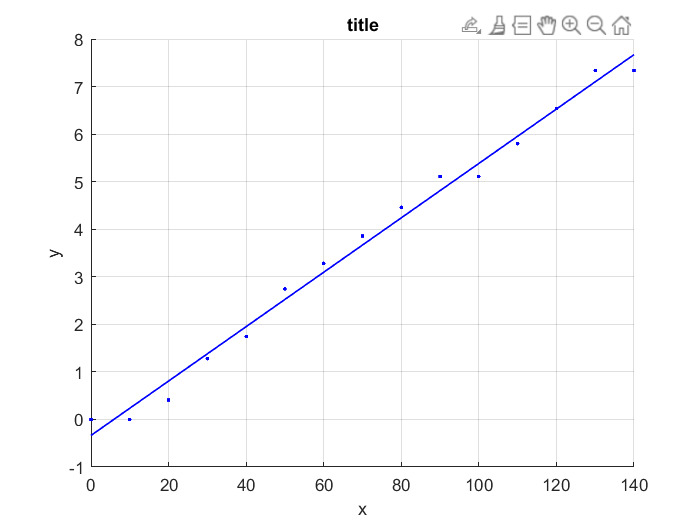

hold off;

## Таблицы необходимых подсчётов

middle_values = table_for_middle_values(cell2mat(MV))

middle_values = 1×5 table
    middle_x    middle_y    middle_xy    middle_x_square    middle_y_square
    ________    ________    _________    _______________    _______________

       70        3.6675      363.49          6766.7             19.618     


save_middle_values = string(inputdlg('Do you want to save the middle values table? (yes/no)'));
if save_middle_values == "yes"
    writetable(middle_values, 'middle-values.xls', 'Sheet', 1, 'Range', 'A1:Z100')
end
main_values = main_table(cell2mat(SSQ), cell2mat(SSQ_delta))

main_values = 1×3 table
    coeficient    delta_coeficient    epsilon_coeficient
    __________    ________________    __________________

     0.057197        0.0014707              2.5713      


save_main_values = string(inputdlg('Do you want to save the main values table? (yes/no)'));
if save_middle_values == "yes"
    writetable(main_values, 'main-values.xls', 'Sheet', 1, 'Range', 'A1:Z100')
end